%% Evaluation of antenna results from CST
clc; clear all; close all;
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code


Parameters

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9800    0.9810    0.9820    0.9830    0.9840    0.9850    0.9860    0.9870    0.9880    0.9890    0.9900    0.9910    0.9920    0.9930    0.9940    0.9950    0.9960    0.9970    0.9980    0.9990


T_coh = 0.0038

N_packets_coh = 12

T = 144

SNR_dB = 36.5005


%% 1. Configuration
fileName_dB    = 'CST_S_Zmax(1)_Zmin(2)_cao2022broadband_28_GHz_varswip_l_1_l_6.txt';
fileName_phase = 'CST_phase_S_Zmax(1)_Zmin(2)_cao2022broadband_28_GHz_varswip_l_1_l_6.txt';
coordFileName  = 'L5_TTD_A_Type_2_polygon_CST_xyz_triplets.txt';

try
    coordFormulas = readcell(coordFileName, 'Delimiter', ' ', 'MultipleDelimsAsOne', true);
    simData_dB    = parseCstMultiSimWithParams(fileName_dB,    coordFormulas);
    simData_phase = parseCstMultiSimWithParams(fileName_phase, coordFormulas);
catch ME
    error('Error reading files: %s', ME.message);
end

numSims = numel(simData_dB);

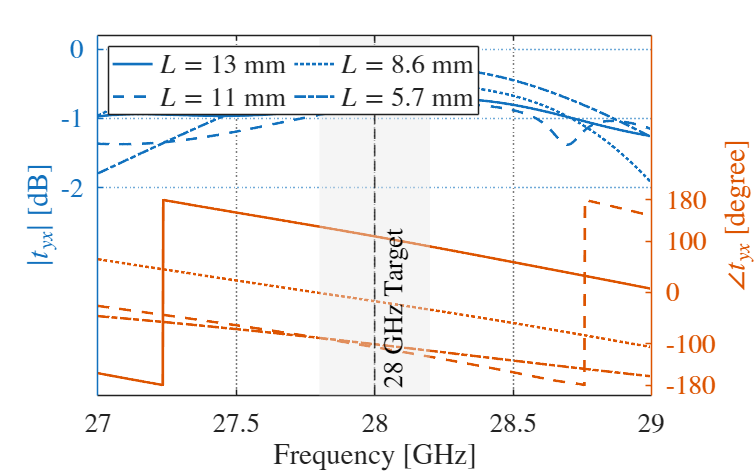


%% Plotting
selection = [1 2 3 5];

%% 3. Plot Generation
line_style = {'-','--',':','-.'};
figure('Color', 'w', 'Units', 'pixels', 'Position', [100, 100, 800, 500]);
line_handles = zeros(1, length(selection));

yyaxis left
hold on;
k = 1;
for i = selection
    line_handles(k) = plot(simData_dB(i).Freq, simData_dB(i).Value, ...
        'LineStyle', line_style{k}, 'LineWidth', 2);
    k = k + 1;
end
ylabel('$|t_{yx}|$ [dB]', 'FontSize', font, 'Interpreter', 'latex');
ylim([-5.0, 0.2]);
set(gca, 'YTick', [-2,-1,0]);
set(gca, 'YTickLabel', {'-2','-1','0'}, 'TickLabelInterpreter', 'latex');


yyaxis right
hold on;
k = 1;
for i = selection
    plot(simData_phase(i).Freq, simData_phase(i).Value, ...
        'LineStyle', line_style{k}, 'LineWidth', 2, 'HandleVisibility', 'off');
    k = k + 1;
end

%% 4. Engineering Annotations
xline(fc/1e9, '--k', strcat('$',num2str(fc/1e9),'$ GHz Target'), 'LineWidth', 1.2, ...
    'LabelVerticalAlignment', 'bottom', 'Interpreter', 'latex','FontSize',font);
patch([27.8 28.2 28.2 27.8], [-200 -200 500 500], [0.9 0.9 0.9], ...
    'FaceAlpha', 0.4, 'EdgeColor', 'none', 'HandleVisibility', 'off');

legend_text = cell(1, length(selection));
for m = 1:length(legend_text)
    legend_text{m} = strcat('$L=', num2str(simData_dB(selection(m)).TotalLength,2), '$ mm');
end
legend(line_handles, legend_text, 'Location', 'northwest', 'NumColumns', 2, ...
    'Interpreter', 'latex', 'FontSize', font);

%% 5. Formatting
set(gca, 'YTick', [-180,-100,0,100,180]);
set(gca, 'YTickLabel', {'-180','-100','0','100','180'}, 'TickLabelInterpreter', 'latex');

grid on;
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.6;
box on;
xlabel('Frequency [GHz]', 'FontSize', font, 'Interpreter', 'latex');
ylabel('$\angle t_{yx}$ [degree]', 'FontSize', font, 'Interpreter', 'latex');
xlim([min(simData_phase(selection(end)).Freq), max(simData_phase(selection(end)).Freq)]);
set(gca, 'FontSize', font);

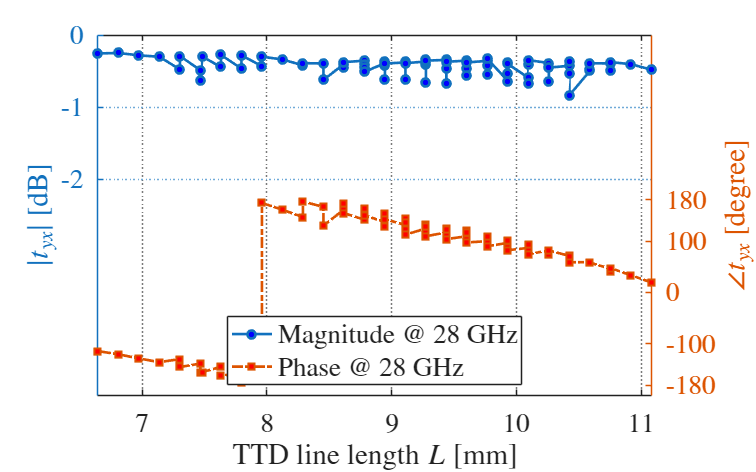


%% Extract Values at target frequency
targetFreq = fc/1e9;
numSims    = numel(simData_dB);

lengths   = zeros(1, numSims);
ampAt28   = zeros(1, numSims);
phaseAt28 = zeros(1, numSims);

for i = 1:numSims
    lengths(i) = simData_dB(i).TotalLength;
    [~, freqIdx] = min(abs(simData_dB(i).Freq - targetFreq));
    ampAt28(i)   = simData_dB(i).Value(freqIdx);
    phaseAt28(i) = simData_phase(i).Value(freqIdx);
end

[lengths, sortIdx] = sort(lengths);
ampAt28   = ampAt28(sortIdx);
phaseAt28 = phaseAt28(sortIdx);

%% Parametric Plot vs. Length
figure('Color', 'w', 'Units', 'pixels', 'Position', [100, 100, 800, 500]);

yyaxis left
%identify which elements are of different length
[~,idx_length]=unique(lengths);
idx_length=idx_length(2:end-1);
%deleting points
idx_length=vertcat(idx_length(1:16),idx_length(19:21),idx_length(23:27),idx_length(29),idx_length(31:86),idx_length(88:end));

h1 = plot(lengths(idx_length), ampAt28(idx_length), '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', ...
    'DisplayName', sprintf('Magnitude @ %g GHz', targetFreq));

ylabel('$|t_{yx}|$ [dB]', 'FontSize', font, 'Interpreter', 'latex');
grid on;
axis([lengths(idx_length(2)),lengths(idx_length(end-1)),-5.0, 0]);
set(gca, 'YTick', [-2,-1,0]);
set(gca, 'YTickLabel', {'-2','-1','0'}, 'TickLabelInterpreter', 'latex');

yyaxis right
h2 = plot(lengths(idx_length), phaseAt28(idx_length), '-.s', 'LineWidth', 2, 'MarkerFaceColor', 'r', ...
    'DisplayName', sprintf('Phase @ %g GHz', targetFreq));
ylabel('$\angle t_{yx}$ [degree]', 'FontSize', font, 'Interpreter', 'latex');

xlabel('TTD line length $L$ [mm]', 'FontSize', font, 'Interpreter', 'latex');
xlim([min(lengths) - 0.1, max(lengths) + 0.1]);
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.6;
box on;
set(gca, 'FontSize', font);
legend([h1, h2], 'Location', 'best', 'Interpreter', 'latex', 'FontSize', font);
set(gca, 'YTick', [-180,-100,0,100,180]);
set(gca, 'YTickLabel', {'-180','-100','0','100','180'}, 'TickLabelInterpreter', 'latex');
axis([lengths(idx_length(2)),lengths(idx_length(end-1)),-200, 500]);



%% ========================================================================
%% LOCAL FUNCTIONS
%% ========================================================================

function sims = parseCstMultiSimWithParams(filename, coordFormulas)
    fid = fopen(filename, 'r');
    if fid == -1, error('Could not open file "%s".', filename); end

    sims = struct('Freq', {}, 'Value', {}, 'Params', {}, 'TotalLength', {});
    currentSim      = 0;
    freqBlock       = [];
    valBlock        = [];
    currentParamStr = '';

    while ~feof(fid)
        line = strtrim(fgets(fid));
        if isempty(line) || startsWith(line, '-------') || strcmp(line, '-1')
            continue;
        end
        if startsWith(line, '#Parameters = {')
            if ~isempty(freqBlock)
                currentSim = currentSim + 1;
                sims(currentSim).Freq        = freqBlock;
                sims(currentSim).Value       = valBlock;
                sims(currentSim).TotalLength = calculateLineLength(currentParamStr, coordFormulas);
                freqBlock = []; valBlock = [];
            end
            currentParamStr = line;
            continue;
        end
        if startsWith(line, '#"Frequency'), continue; end
        if ~startsWith(line, '#')
            data = sscanf(line, '%f');
            if numel(data) >= 2
                freqBlock(end+1, 1) = data(1);
                valBlock(end+1, 1)  = data(2);
            end
        end
    end

    if ~isempty(freqBlock)
        currentSim = currentSim + 1;
        sims(currentSim).Freq        = freqBlock;
        sims(currentSim).Value       = valBlock;
        sims(currentSim).TotalLength = calculateLineLength(currentParamStr, coordFormulas);
    end
    fclose(fid);
end

function totalLength = calculateLineLength(paramStr, coordFormulas)
    % 1. Parse CST parameter string into local workspace variables
    paramStr = strrep(paramStr, '#Parameters = {', '');
    paramStr = strrep(paramStr, '}', '');
    pairs    = split(paramStr, ';');

    for k = 1:numel(pairs)
        subPair = strtrim(pairs{k});
        if isempty(subPair), continue; end
        eqIdx = strfind(subPair, '=');
        if ~isempty(eqIdx)
            varName = strtrim(subPair(1:eqIdx(1)-1));
            varVal  = str2double(subPair(eqIdx(1)+1:end));
            eval([varName ' = ' num2str(varVal, 16) ';']);
        end
    end

    % --- Fallbacks for absent segment variables ---
    if ~exist('l_3', 'var'), l_3 = l_1; end
    if ~exist('l_4', 'var'), l_4 = l_2; end
    if ~exist('l_5', 'var'), l_5 = 0; end
    if ~exist('l_6', 'var'), l_6 = 0; end
    if ~exist('l_7', 'var'), l_7 = 0; end
    if ~exist('l_8', 'var'), l_8 = 0; end

    % --- Short-name aliases used by coord formula file ---
    % TTD segment lengths: l_1..l_6
    l_1 = l_1;
    l_2 = l_2;
    l_3 = l_3;
    l_4 = l_4;
    l_5 = l_5;
    l_6 = l_6;
    % PCB layer z-heights: l_7..l_10 -> z_L3..z_L6 (TTD stripline layers)
    % Mapping: coord file l_7=z_L3, l_8=z_L4, l_9=z_L5, l_10=z_L6
    if exist('z_L3',  'var'), l_7  = z_L3;  end
    if exist('z_L4',  'var'), l_8  = z_L4;  end
    if exist('z_L5',  'var'), l_9  = z_L5;  end
    if exist('z_L6',  'var'), l_10 = z_L6;  end

    % 2. Evaluate polyline point coordinates
    numPoints = size(coordFormulas, 1);
    X = zeros(numPoints, 1);
    Y = zeros(numPoints, 1);

    for i = 1:numPoints
        xExpr = coordFormulas{i, 1};
        if isnumeric(xExpr), xExpr = num2str(xExpr); end
        yExpr = coordFormulas{i, 2};
        if isnumeric(yExpr), yExpr = num2str(yExpr); end
        X(i) = eval(vectorizedString(xExpr));
        Y(i) = eval(vectorizedString(yExpr));
    end

    % 3. Euclidean distance along path
    dx = diff(X);
    dy = diff(Y);
    totalLength = sum(sqrt(dx.^2 + dy.^2));
end

function s = vectorizedString(s)
    s = char(s);
    s = strrep(s, '*', '.*');
    s = strrep(s, '/', './');
end

function addingPathParentFolderByName(targetName)
    currFolder = pwd;
    found = false;
    while true
        [parentFolder, currentName] = fileparts(currFolder);
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        currFolder = parentFolder;
    end
    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end